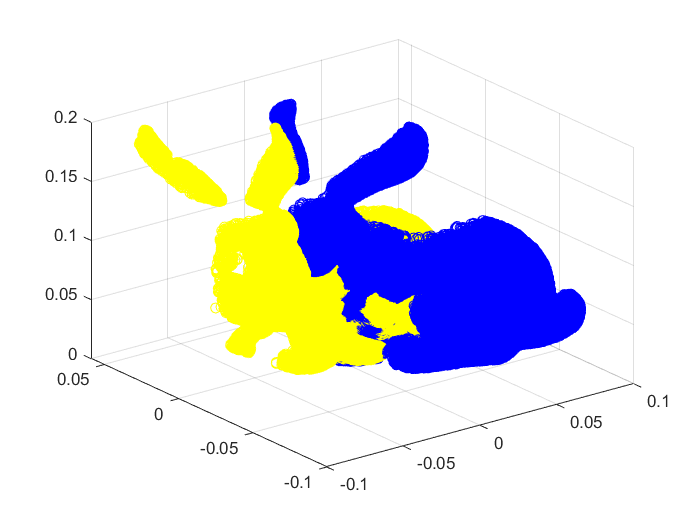

clear all;
close all;
clc;

P=load("bunny txt\bun000 - Cloud.txt");
X=load("bunny txt\bun045 - Cloud.txt");

% 行数统一
[pm, ~] = size(P);
[xm, ~] = size(X);
if pm >= xm
    P = P(1:xm,:);
else
    X = X(1:pm,:);
end
 
plot_3d_2(P, X, -90,'y','b'); % 显示出当前两个点集


itermax = 1000;
d0 = 0.00001

d0 = 1.0000e-05


% 四元数法
[Pre_sys,~,d1] = icp_sys(P,X,itermax,d0);

历时 1.074202 秒。


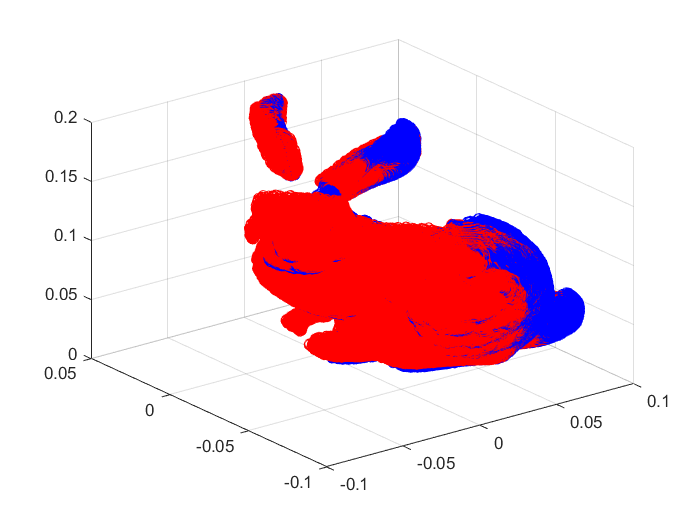

 
figure;
plot_3d_2(Pre_sys, X, -90, 'r', 'b');



%SVD
[Pre_svd,~,d2] = icp_svd(P, X,itermax,d0);

历时 0.887739 秒。


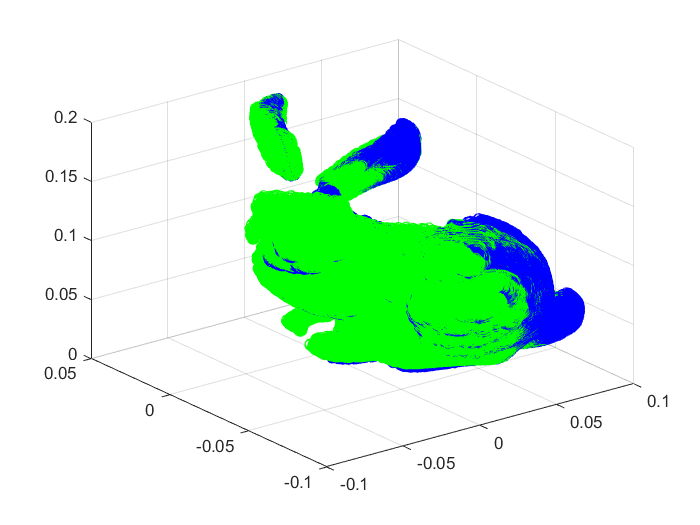


figure;
plot_3d_2(Pre_svd, X, -90, 'g', 'b');

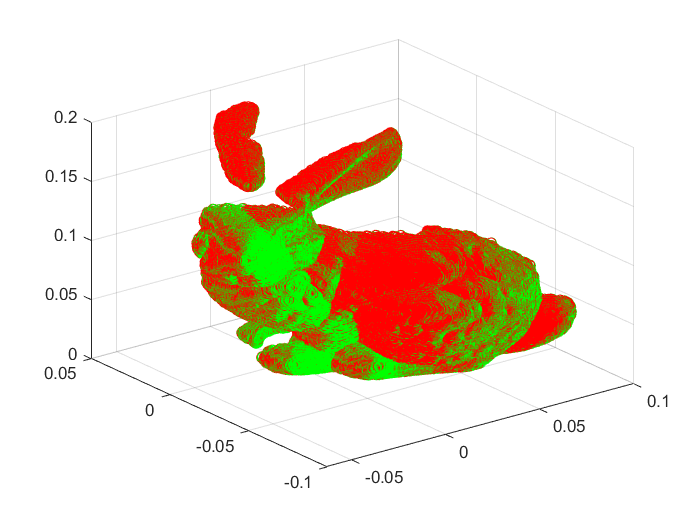


figure;
plot_3d_2(Pre_svd, Pre_sys, -90, 'g', 'r');